syms x y
k = 1000;
b = 0.5;
a = b*k;
f = a*x^2+b*y^2;
t = 10^-5;
K = 100000;
x_init1 = 1;
y_init1 = -1;
tic
[A, B] = WGD(x_init1,y_init1,K,t,a,b);
toc

Elapsed time is 0.019905 seconds.


fprintf('x* = %d', A(K-1,1))

x* = -3.268747e-70

fprintf('y* = %d', A(K-1,2))

y* = 1.907291e-69

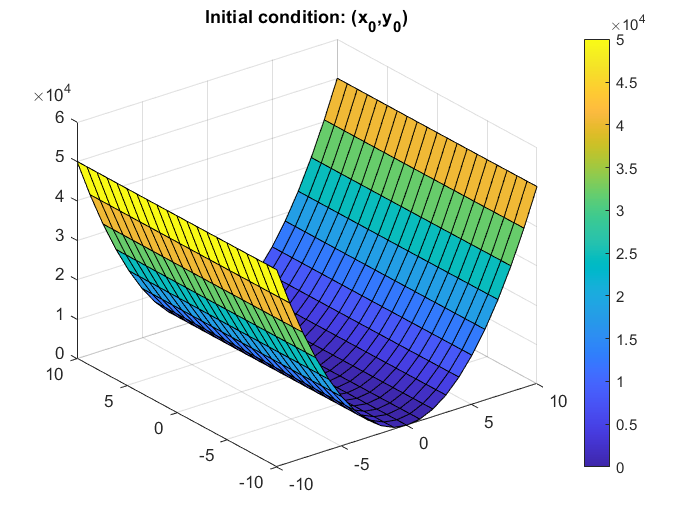

[X,Y] = meshgrid(-10:1:10,-10:1:10);
Z = a*X.^2+b*Y.^2;
surf(X,Y,Z)
title('Initial condition: (x_0,y_0)')
colorbar

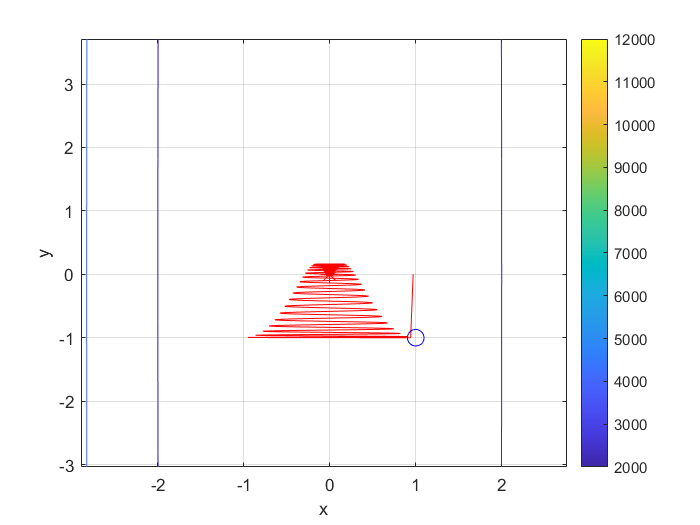

fcontour(f,'fill','off','MeshDensity',500)
grid on
xlabel('x')
ylabel('y')
hold on
x = A(:,1);
y = A(:,2);
plot(x,y,'red')
scatter(x_init1,y_init1,100,'blue','O')
scatter(A(K-1,1),A(K-1,2),100,'red','*')
colorbar
hold off

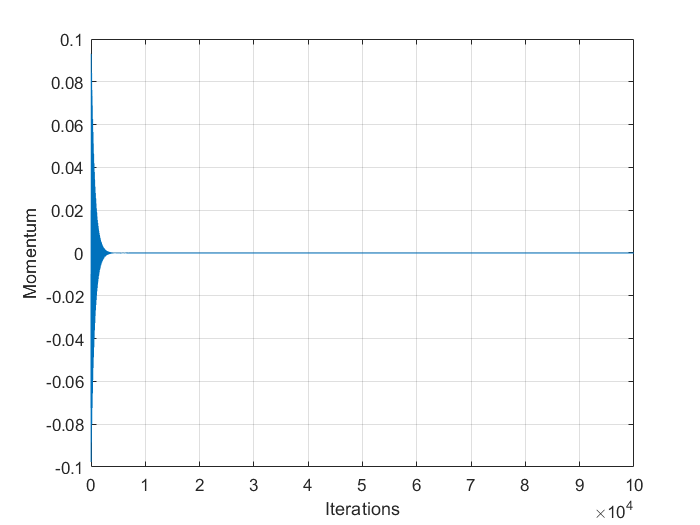

ax = gca;
t = B(:,1);
plot(t)
grid on
xlabel('Iterations')
ylabel('Momentum')

function [A,B] = WGD(x_init,y_init,K,t,a,b)
k = 1;
x_k0 = x_init;
y_k0 = y_init;
x_k1 = x_init - t * grad_f_x(x_init,y_init,a);
y_k1 = y_init - t * grad_f_y(x_init,y_init,b);
A = zeros(K-1,2);
B = zeros(K-1,1);
while (k < K)
beta_x = sqrt(t)+ k*t*((x_k1 - x_k0)'*(x_k1 - x_k0));
x_k2 = x_k1 +(1- beta_x)*(x_k1 - x_k0) - t*grad_f_x(x_k1,y_k1,a);
B(k) = (x_k1 - x_k0);
A(k,1)= x_k2 ;
k =k + 1;
x_k0 = x_k1;
x_k1 = x_k2;
beta_y = sqrt(t)+ k*t*((y_k1 - y_k0)'*(y_k1 - y_k0));
y_k2 = y_k1 +(1- beta_y)*(y_k1 - y_k0) - t*grad_f_y(x_k1,y_k1,b);
A(k,2)= y_k2 ;
y_k0 = y_k1;
y_k1 = y_k2;
end
end
function g1 = grad_f_x(x,~,a)
 g1 = 2*a*x;          
end
function g2 = grad_f_y(~,y,b)
 g2 = 2*b*y;
end
